パラメータ設定

params.sigma = 10;
params.beta = 8/3;
params.rho = 28;
params.eta = sqrt(params.beta*(params.rho-1));

データ生成

[t,y] = lorenzgen(params);

描画

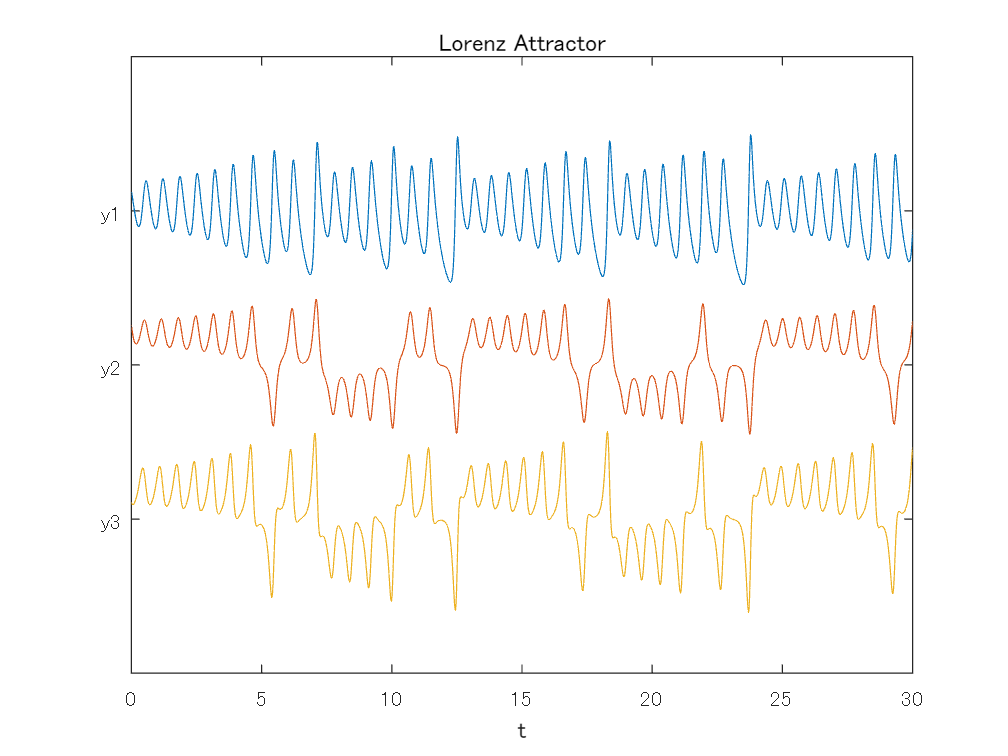

plot(t,[y(:,1)+15 y(:,2) y(:,3)-40]);
axis([0 30 -80 80])
set(gca,'ytick',[-40 0 40],'yticklabel',{'y3','y2','y1'})
xlabel('t')
title('Lorenz Attractor')

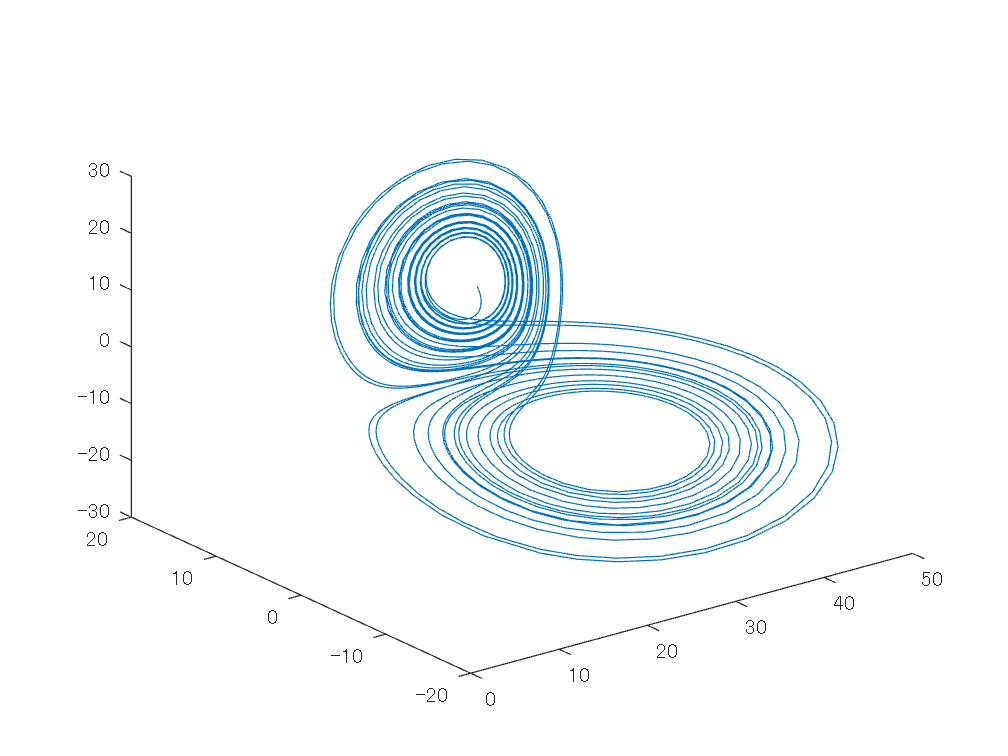


figure
h1 = plot3(y(:,1),y(:,2),y(:,3));

遅延埋め込みとデータ行列生成

nDelay = 1;

ts = [];
for iCol = 1:size(y,2)
    c = y(1:nDelay+1,iCol);
    r = y(nDelay+1:end,iCol);
    h = hankel(c,r);
    ts = cat(3,ts,h);
end

X = reshape(permute(ts,[2 1 3]),size(ts,2),[]);


学習方法

- ` Classify `$\{\mathbf{x}_k\}_k\in\mathcal{M}$` into `$Q$`-clusters by using Gaussian mixture model (GMM), where the dimension is reduced if possible.`

- ` Set `$\{\hat{\mathbf{a}}_c\}_c\mathcal{M}$` by the mean vectors `$\{\mathbf{\mu}_c\}_c$` of the `$c$`-th Gaussian obtained by Step~1.`

- ` Design analysis LSUNs `$\{\hat{\mathbf{\Psi}}_c\}_c$` from `$\{\mathbf{x}_k\}_k$`.`

- ` Obtain linear operators `$\{\hat{\mathbf{K}}_c\}_c$` and biases `$\{\hat{\mathbf{b}}_c\}_c$` from `$\{\mathbf{x}_k\}_k$` by using linear AEs with LSUN.`

Step 1 クラスタリング

nGauss = 4;
options = statset('MaxIter',1000);

Sigma = 'full';
SharedCovariance = false;

gmfit = fitgmdist(X,nGauss,'CovarianceType',Sigma, ...
    'SharedCovariance',SharedCovariance,'Options',options); % Fitted GMM
clusterX = cluster(gmfit,X); % Cluster index
if nDelay == 0
    hold on
    plot3(gmfit.mu(:,1),gmfit.mu(:,2),gmfit.mu(:,3),'kx','LineWidth',2,'MarkerSize',10)
end
hold off

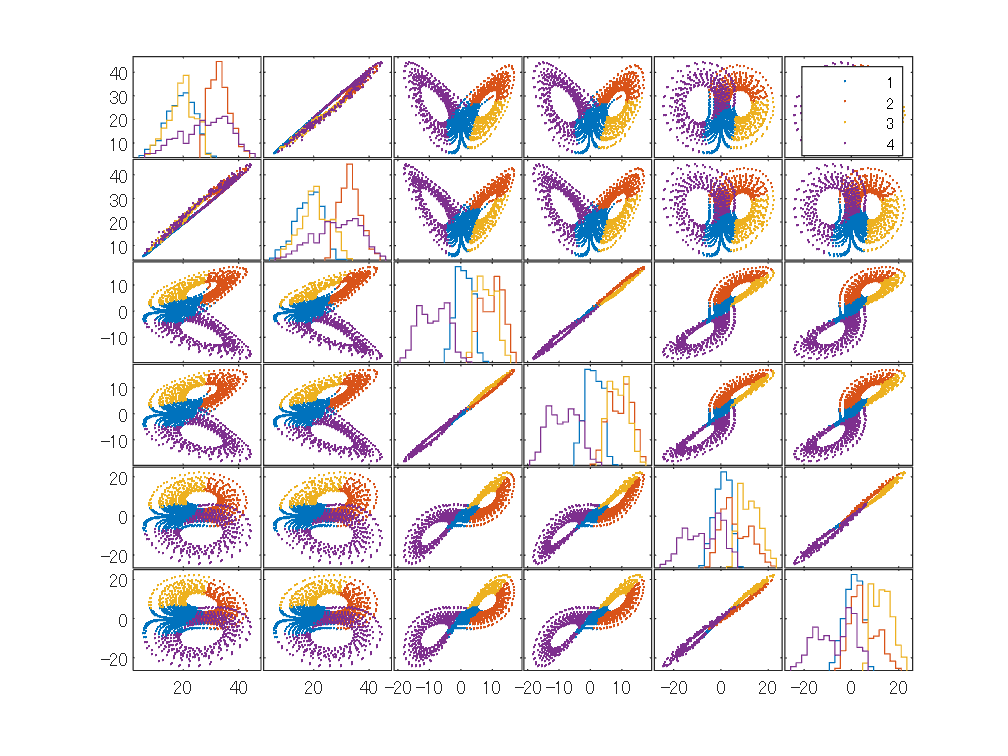


figure
gplotmatrix(X,[],clusterX)

Step 2 平均ベクトルの算出

acT = gmfit.mu; % Q x 3(d+1)
ac = acT.'; % 3(d+1) x Q

Step 3 PCA (LSUN) の設計

for c = 1:nGauss
    c
    Sigmac = gmfit.Sigma(:,:,c);
    Psi(:,:,c) = pcacov(Sigmac); % pca(Zc);
end

c = 1

c = 2

c = 3

c = 4

%plotmatrix(Zc)
%plotmatrix((Psi(:,:,c)*Zc.').')


Step 4 線形変換 Pc とバイアス bc の導出

P = 2; % # of channels
for c = 1:nGauss
    Ic = find(clusterX == c);
    Ic = Ic(1:end-1);
    %
    X0cT = X(Ic,:);
    X1cT = X(Ic+1,:);
    Z0cT = X0cT-acT(c,:);
    %
    Psic = Psi(:,:,c);
    PsiZ0c = Psi(:,:,c)*Z0cT.';
    SPsiZ0c = PsiZ0c(1:P,:);
    Q_bc = (X1cT).'*pinv([SPsiZ0c; ones(1,size(SPsiZ0c,2))]);
    %
    Qc = Q_bc(:,1:end-1);
    bc(:,c) = Q_bc(:,end);
    %
    Pc(:,:,c) = Psic(1:P,:)*Qc;
end

学習パラメータ

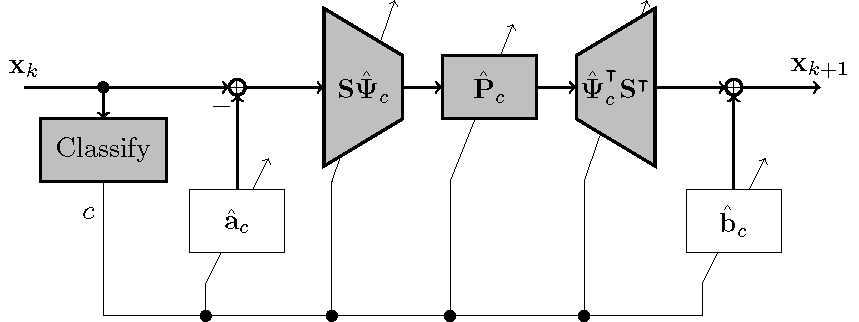


$$\mathbf{S}\hat{\mathbf{\Psi}}_c\in\mathbb{R}^{P\times N}$$


SPsic = Psi(1:P,:,:)

SPsic = SPsic(:,:,1) =

    0.6274   -0.3463   -0.0735   -0.1870   -0.6648    0.0648
    0.6005   -0.3324   -0.1021    0.1978    0.6891   -0.0671


SPsic(:,:,2) =

    0.1232    0.6476   -0.0672    0.6500    0.2802   -0.2446
    0.2406    0.5774   -0.4926   -0.5633   -0.0681    0.2101


SPsic(:,:,3) =

    0.4566   -0.5303   -0.1843    0.4885   -0.4441    0.2011
    0.5564   -0.4091   -0.1086   -0.4563    0.5110   -0.2049


SPsic(:,:,4) =

    0.5489    0.4024    0.1016   -0.4592   -0.5219    0.2080
    0.4527    0.4790    0.3422    0.5189    0.3902   -0.1641



$$\hat{\mathbf{P}}_c\in\mathbb{R}^{P\times P}$$


Pc

Pc = Pc(:,:,1) =

    1.0362   -0.0776
   -0.0632    1.0360


Pc(:,:,2) =

    1.0414   -0.4587
    0.0628    0.8656


Pc(:,:,3) =

    0.9379    0.2610
   -0.1410    0.8727


Pc(:,:,4) =

    1.0389   -0.2479
    0.1157    0.9122



$$\hat{\mathbf{a}}_c\in\mathbb{R}^{N}$$


ac

ac =    18.9183   33.2055   19.4039   28.1605
   18.2555   33.0421   20.6589   28.4654
    1.0362   10.0492    8.1311   -8.6488
    0.9658    9.4488    8.9886   -8.5387
    0.5509    6.2220   12.2017   -7.2176
    0.6129    5.1907   13.1751   -6.9488



$$\hat{\mathbf{b}}_c\in\mathbb{R}^N$$


bc

bc =    18.2531   33.0428   20.6637   28.4640
   17.6447   32.6558   22.1654   28.7323
    0.9627    9.4490    8.9781   -8.5427
    0.9144    8.7854    9.8298   -8.4003
    0.6118    5.1865   13.1573   -6.9427
    0.6821    4.2258   13.9489   -6.6396


Classifier

classify = @(x) cluster(gmfit,x.')

classify = 値をもつ function_handle :
    @(x)cluster(gmfit,x.')


シミュレーション

function [t,y] = lorenzgen(params)

sigma = params.sigma;
beta = params.beta;
rho = params.rho;
eta = params.eta;

A = [ -beta 0 eta;
    0 -sigma sigma;
    -eta rho -1 ];
v0 = [rho-1 eta eta]';
y0 = v0 + [3 2 -4]';
tspan = [0 30];

[t,y] = ode45(@(t,y) lorenzeqn(t,y,A), tspan, y0);
end

function ydot = lorenzeqn(t,y,A)

A(1,3) = y(2);
A(3,1) = -y(2);
ydot = A*y;

end